# RVC2: Chapter 16 - Advanced Visual Servoing

## 16.1 XY/Z partitioned IBVS

principal point not specified, setting it to centre of image plane
cam = 
name: default [central-perspective]                     
  focal length:   0.008                                 
  pixel size:     (1e-05, 1e-05)                        
  principal pt:   (512, 512)                            
  number pixels:  1024 x 1024                           
  pose:           t = (0, 0, 0), RPY/yxz = (0, 0, 0) deg


creating new figure for camera


h =   Axes with properties:

             XLim: [0 1024]
             YLim: [0 1024]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties

make axes


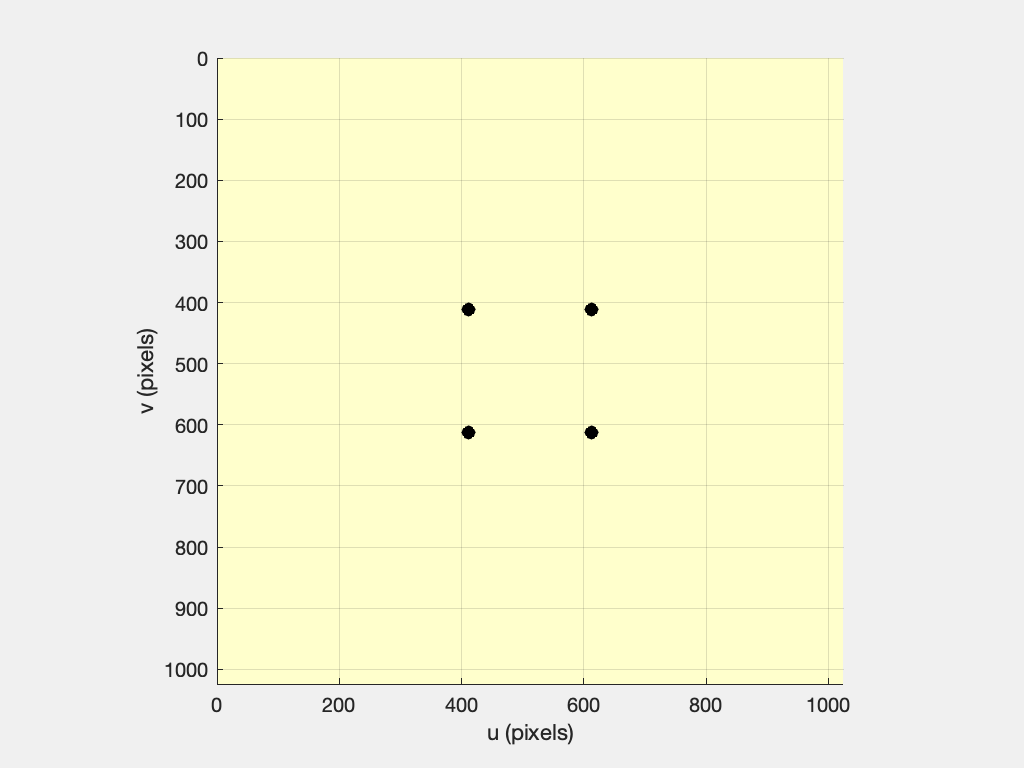

ans =   Simulink.SimulationOutput:

                   tout: [8001x1 double] 
                   yout: [1x1 struct] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


sl_partitioned
sim('sl_partitioned')

## 16.2 IBVS polar

cam = CentralCamera('default')

principal point not specified, setting it to centre of image plane
cam = 
name: default [central-perspective]                     
  focal length:   0.008                                 
  pixel size:     (1e-05, 1e-05)                        
  principal pt:   (512, 512)                            
  number pixels:  1024 x 1024                           
  pose:           t = (0, 0, 0), RPY/yxz = (0, 0, 0) deg


T_C0 = SE3(-0.3, 0.2, -2)*SE3.Rz(pi/2);
vs = IBVS_polar(cam, 'pose0', T_C0)

vs = 
Visual servo object: camera=default
   iterations, 0 history
  P= -0.25       -0.25        0.25        0.25              
     -0.25        0.25        0.25       -0.25              
         0           0           0           0              
  C_T0:   t = ( -0.3,  0.2,  -2), R = ( 90deg |  0,  0,  1) 


creating new figure for camera


h =   handle to deleted Axes

make axes


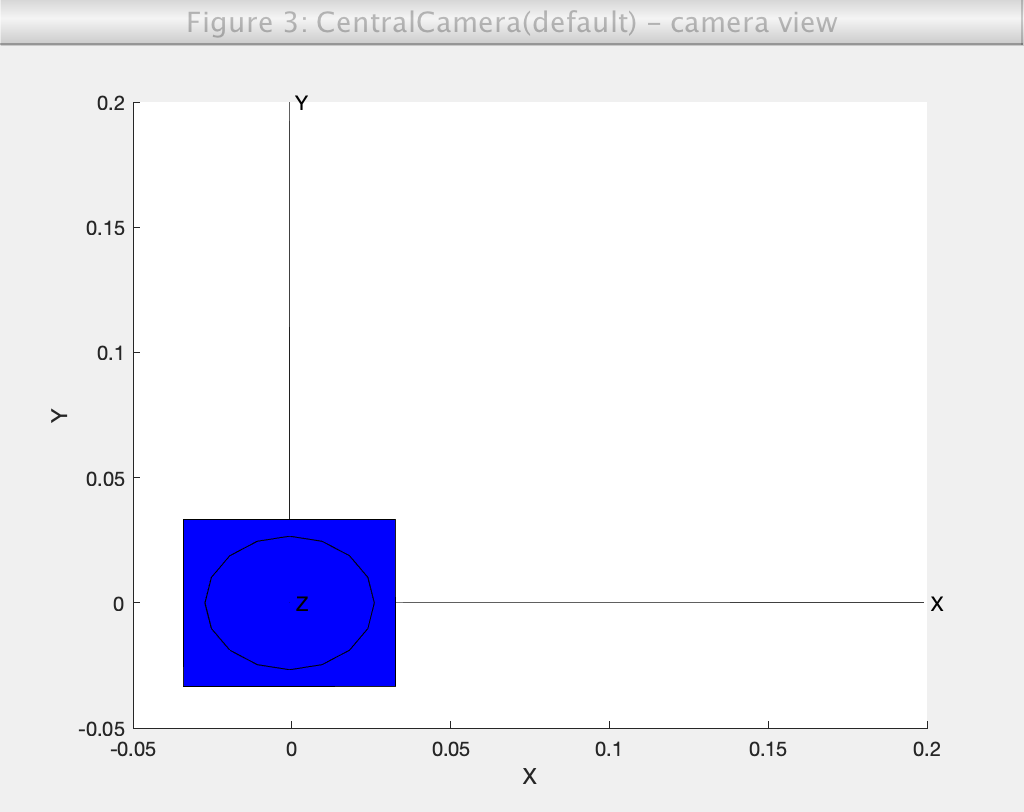

creating new figure for camera


h =   Axes with properties:

             XLim: [0 1024]
             YLim: [0 1024]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties

make axes


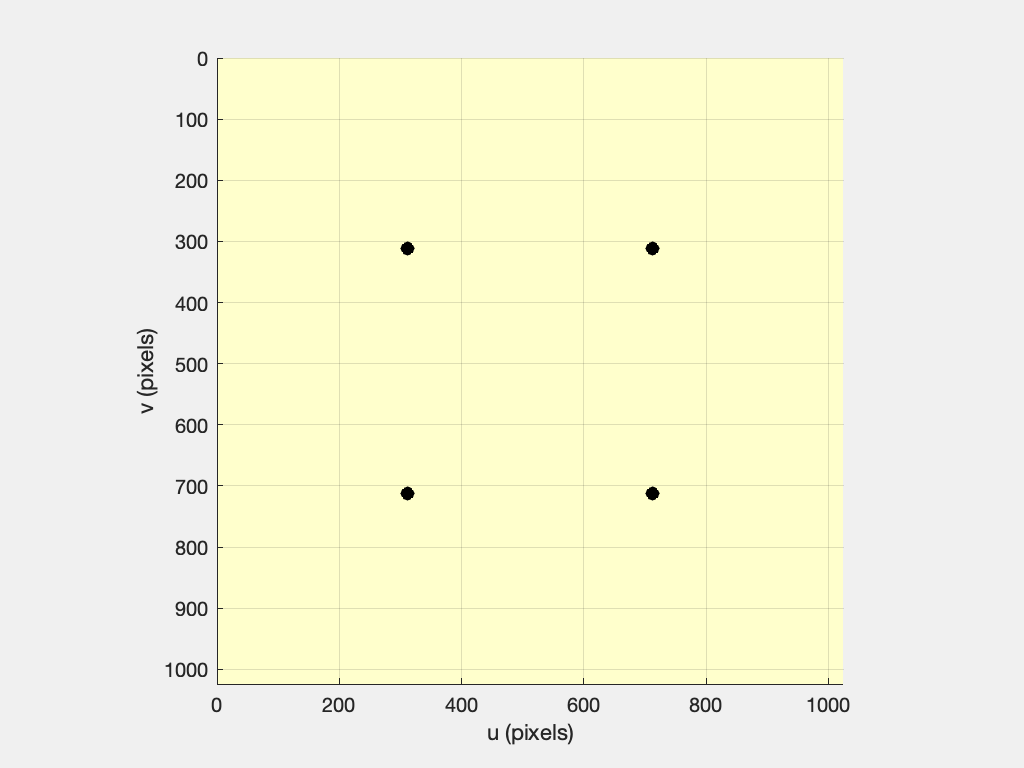

completed on error tolerance



vs.run()

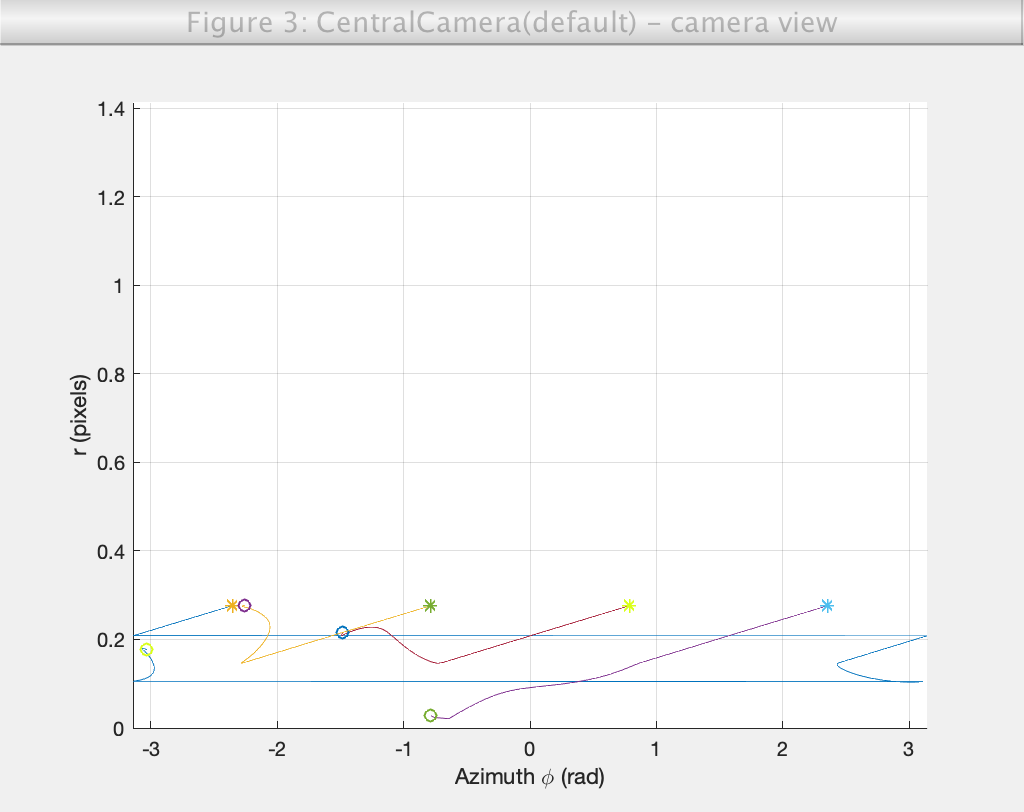


vs.plot_features()

## 16.3 IBVS spherical

cam = SphericalCamera()

principal point not specified, setting it to centre of image plane
cam = 
name: spherical-default [spherical]                     
  pixel size:     (1, 1)                                
  pose:           t = (0, 0, 0), RPY/yxz = (0, 0, 0) deg



T_C0 = SE3(0.3, 0.3, -2)*SE3.Rz(0.4);

vs = IBVS_sph(cam, 'T0', T_C0, 'verbose')

draw image plane in existing axes


ans =   Axes (spherical-default) with properties:

             XLim: [-3.1416 3.1416]
             YLim: [0 3.1416]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.8150]
            Units: 'normalized'

  Show all properties

ans =     -3     3    -3     3    -3     3


ibvs = 
Visual servo object: camera=spherical-default
   iterations, 0 history
  P= -0.25       -0.25        0.25        0.25                        
     -0.25        0.25        0.25       -0.25                        
         0           0           0           0                        
  C_T0:   t = ( 0.3,  0.3,  -2), R = ( 22.9183deg |  0,  0,  1)       
  C*_T_G: t = ( 0,  0,  -1.5), R = ( 57.2958deg |  0,  0,  1)         
ibvs = 
Visual servo object: camera=spherical-default
   iterations, 0 history
  P= -0.25       -0.25        0.25        0.25                        
     -0.25        0.25        0.25       -0.25                        
         0           0           0           0                        
  C_T0:   t = ( 0.3,  0.3,  -2), R = ( 22.9183deg |  0,  0,  1)       
  C*_T_G: t = ( 0,  0,  -1.5), R = ( 57.2958deg |  0,  0,  1)         
ibvs = 
Visual servo object: camera=spherical-default
   iterations, 0 history
  P= -0.25       -0.25        0.25        0.25       

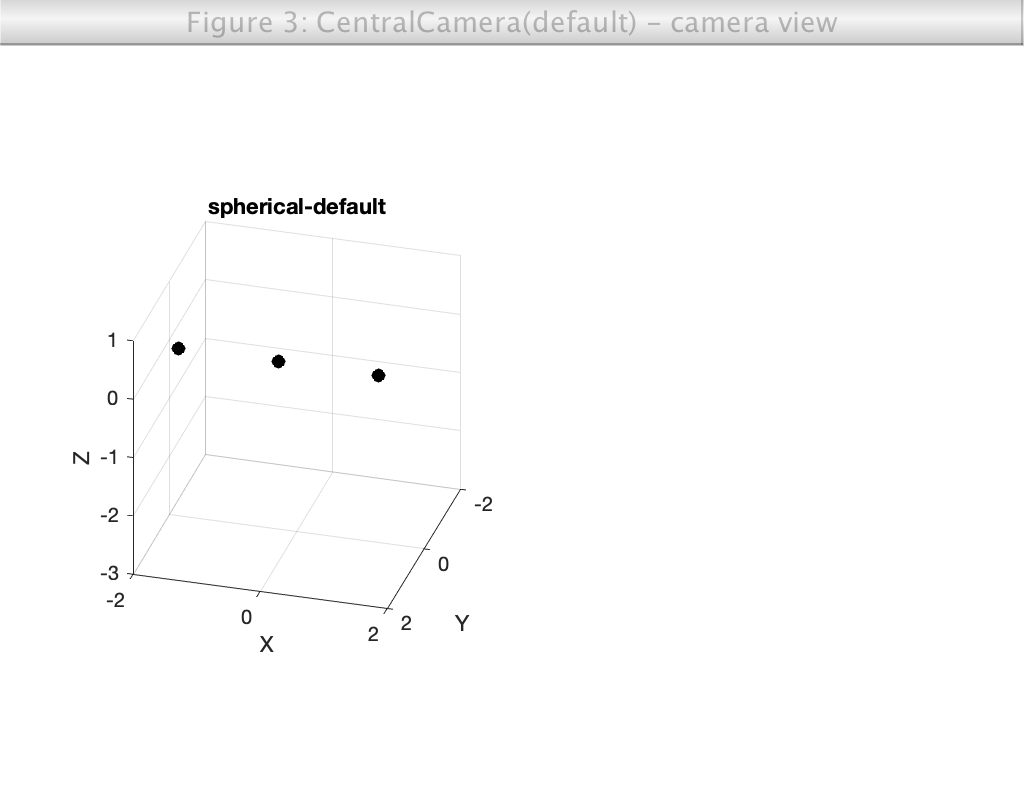

v: -2.755 4.477 -0.155 2.225 1.374 0.319


Invalid or deleted object.
Error in IBVS_sph/step (line 188)
                vs.proj_lines(i).XData = [centre(1) vs.P(1,i)];
Error in VisualServo/run (line 134)
                status = vs.step();

vs.run()

## 16.4 Application: Arm-Type Robot

sl_arm_ibvs

r = sim('sl_arm_ibvs')

q = squeeze(r.find('yout').signals(1).values)';
about(q)

## 16.5.1 Holonomic Mobile Robot


cam = CentralCamera('default', 'focal', 0.002);

V_T_C = SE3(0.2, 0.1, 0.3)*SE3.Rx(-pi/4);

P = [0 0; 1 -1; 2 2]

sl_omni_vs

r = sim('sl_omni_vs')



## 16.5.2 Nonholonomic Mobile Robot

sl_drivepose_vs

r = sim('sl_ibvs')


## 16.6 Application: Aerial Robot

sl_quadrotor_vs

sim('sl_quadrotor_vs')
